% MATLAB Code for Nyquist Plot Analysis of the Uncompensated System
% ------------------------------------------------------------------
% This script defines the open-loop transfer function and generates its
% Nyquist plot to analyze stability via the Nyquist criterion.

% Clear workspace, command window, and close all figures for a clean run
clear;
clc;
close all;

% --- 1. Define the System ---
% Define the numerator and denominator of the open-loop transfer function G_ol(s).
% G_ol(s) = -10.07 / (s^2 + 1806s + 4843)
num_ol = [-10.07];       % Numerator coefficients
den_ol = [1, 1806, 4843]; % Denominator coefficients

% Create the transfer function object for the open-loop system.
G_ol = tf(num_ol, den_ol);

% Display the transfer function in the command window to verify.
disp('Open-Loop Transfer Function (G_ol):');

Open-Loop Transfer Function (G_ol):


G_ol


G_ol =
 
        -10.07
  -------------------
  s^2 + 1806 s + 4843
 
Continuous-time transfer function.
Model Properties


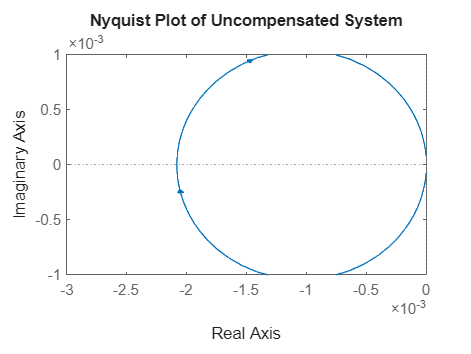


% --- 2. Generate and Display the Nyquist Plot ---
% Create a new figure window for the plot.
figure;

% Generate the Nyquist plot for the open-loop system.
% The nyquist command plots the contour of G_ol(s) in the complex plane
% for s values that encircle the entire right-half plane.
nyquist(G_ol);

% --- 3. Enhance the Plot for Reporting ---
% Add a title to the plot.
title('Nyquist Plot of Uncompensated System');

% Add a grid for better readability.
grid on;

% Set the axis limits to better view the plot and the critical -1 point.
% Since the gain is very small, we need to zoom in.
axis([-0.003 0 -0.001 0.001]); % Adjust these values if needed

% Add labels to the axes.
xlabel('Real Axis');
ylabel('Imaginary Axis');


% The plot helps verify stability by checking encirclements of the -1+j0 point.
